## Homogenous model:

Let $x_{j}(t)$be the state of risk of agent or component $j$, taking real values. For $j = 1, \dots, N$, the $x_{j}(t)$'s are modeled as continuous-time stochastic processes satisfying the system of Itˆo SDEs:


$$$d x_{j}(t)=-h U\left(x_{j}(t)\right) d t+\theta\left(\bar{x}(t)-x_{j}(t)\right) d t+\sigma d w_{j}(t)$$$


where $U(y) = V'(y) = y^3 - y$ and $V(y) =\frac{1}{4} y^{4}-\frac{1}{2} y^{2}$. 

We simulate the above using the Euler scheme:


$$$X_{j}^{n+1} = X_{j}^{n}-h U\left(X_{j}^{n}\right) \Delta t + \sigma \Delta W_{j}^{n+1} +\theta\left(\frac{1}{N} \sum_{k=1}^{N} X_{k}^{n}-X_{j}^{n}\right) \Delta t$
$$


%% Parameters
dt = 0.02;                                
t = 0:dt:10000;                                 
N = 100;

### Varying $\sigma$

Simulations for different $\sigma$ = 1, 2, 4

The system has two (statistically) stable equilibria when σ is below the critical value (approximately $1$ for small $h$).

Fix $h, \theta$:

h = 0.1;                     
theta = 6;  

$\sigma = 1:$ Two stable equilibria

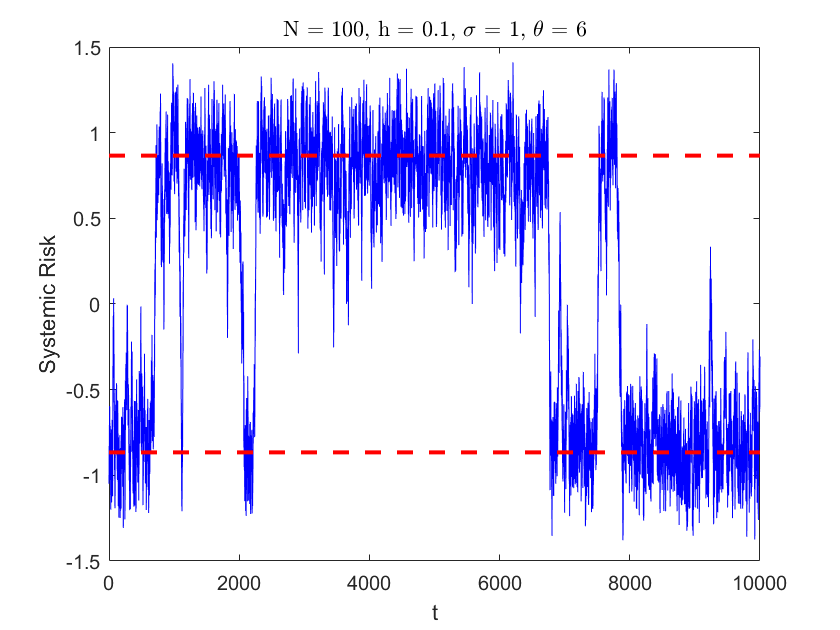

sig = 1;  
PlotSystemicRisk(t, N, h, sig, theta);

$\sigma = 2:$ One stable equilibria

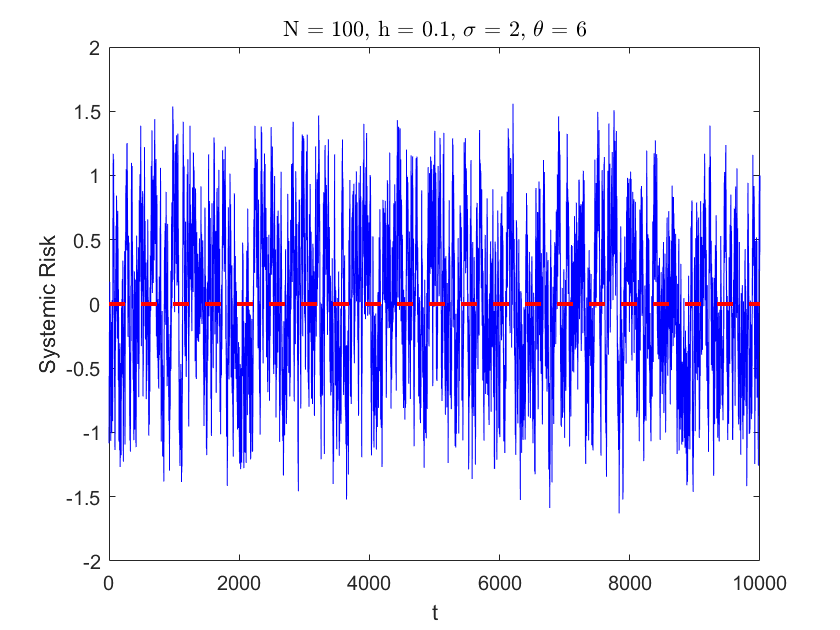

sig = 2;
PlotSystemicRisk(t, N, h, sig, theta);

$\sigma = 4:$ One stable equilibria

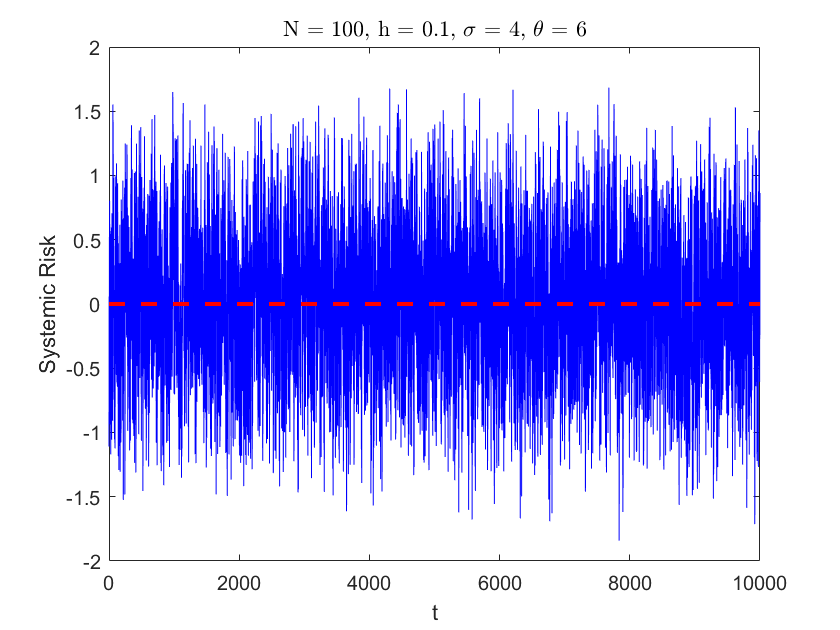

sig = 4;
PlotSystemicRisk(t, N, h, sig, theta);

### Varying $\theta$

Simulations for different $\theta = 5, 1.5, 0.5$

The system has two stable equilibria if θ is above the critical value or otherwise has single stable state 0.

Fix $h, \sigma$:

h = 0.1;
sig = 1;

$\theta = 5$: Two stable equilibria

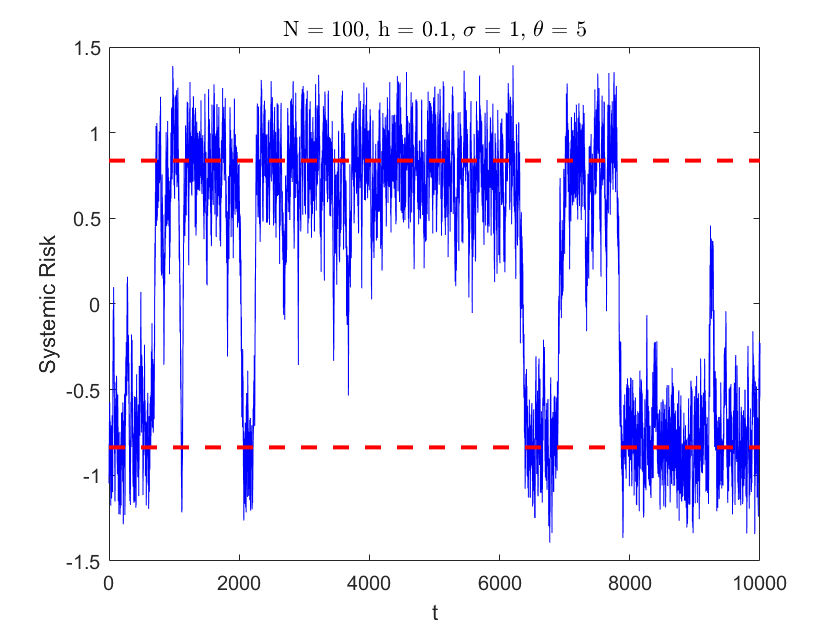

theta = 5;
PlotSystemicRisk(t, N, h, sig, theta);

$\theta = 1.5$: One stable equilibria

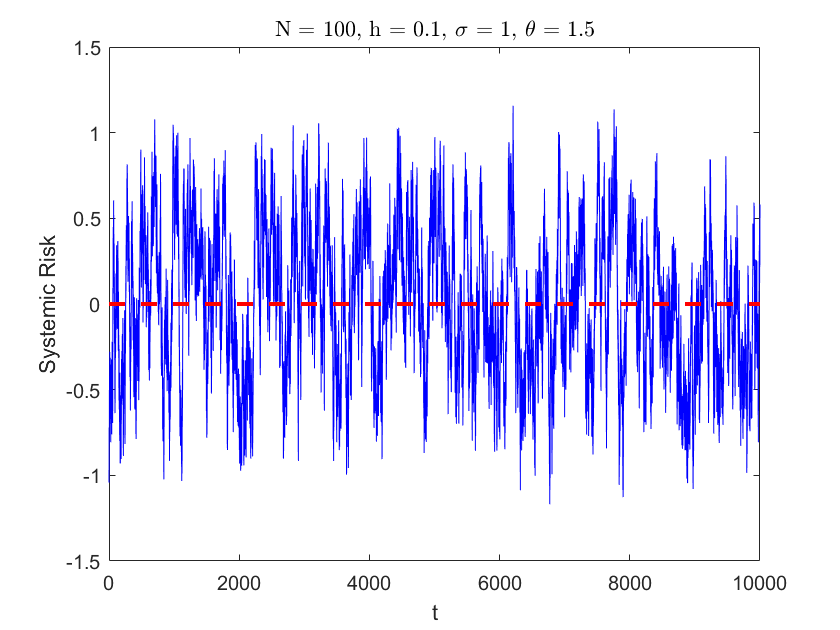

theta = 1.5;
PlotSystemicRisk(t, N, h, sig, theta);

$\theta = 0.5$: One stable equilibria

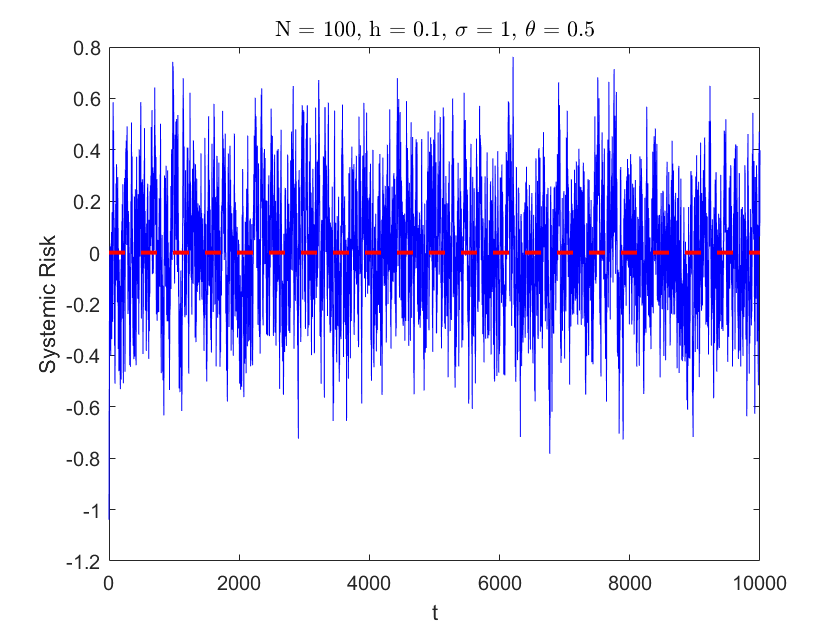

theta = 0.5;
PlotSystemicRisk(t, N, h, sig, theta);

### Varying $h$

Increasing h stabilizes the system. By stability we mean resistance to the transition of the empirical mean of the system from one state to the other.

Simulations for different $h = 0.02, 0.1, 0.5$

Fix $\sigma, \theta$:

sig = 1;
theta = 10;

$h = 0.02$:

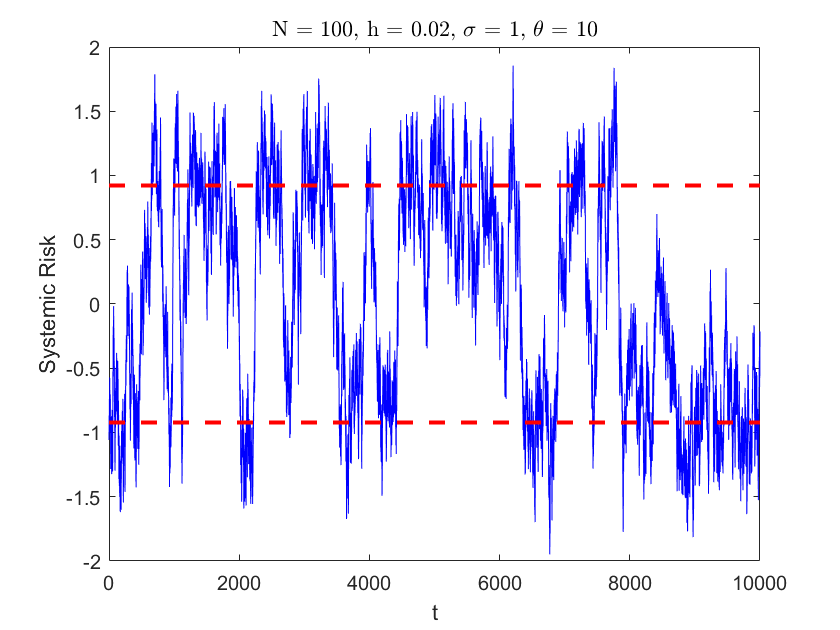

h = 0.02;
PlotSystemicRisk(t, N, h, sig, theta);

$h = 0.1$:

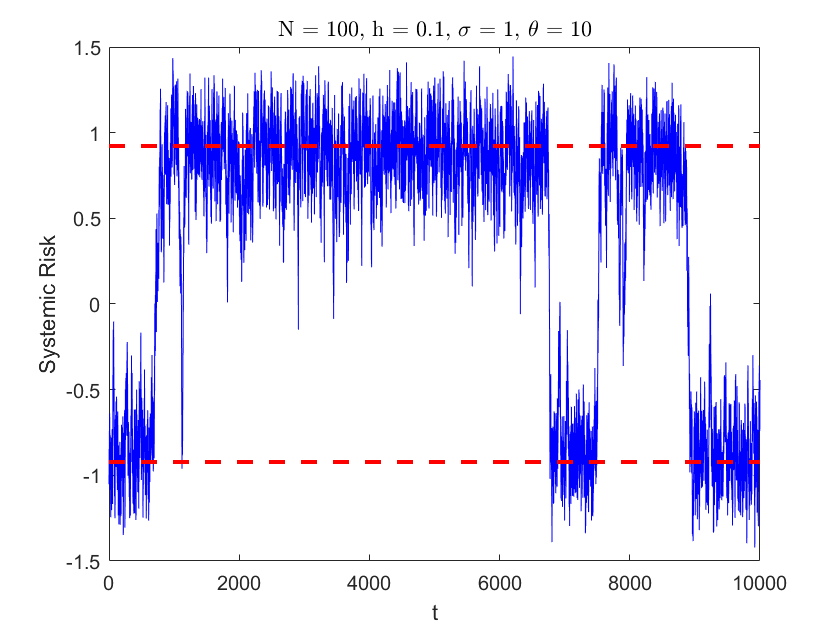

h = 0.1;
PlotSystemicRisk(t, N, h, sig, theta);

$h = 0.5$:

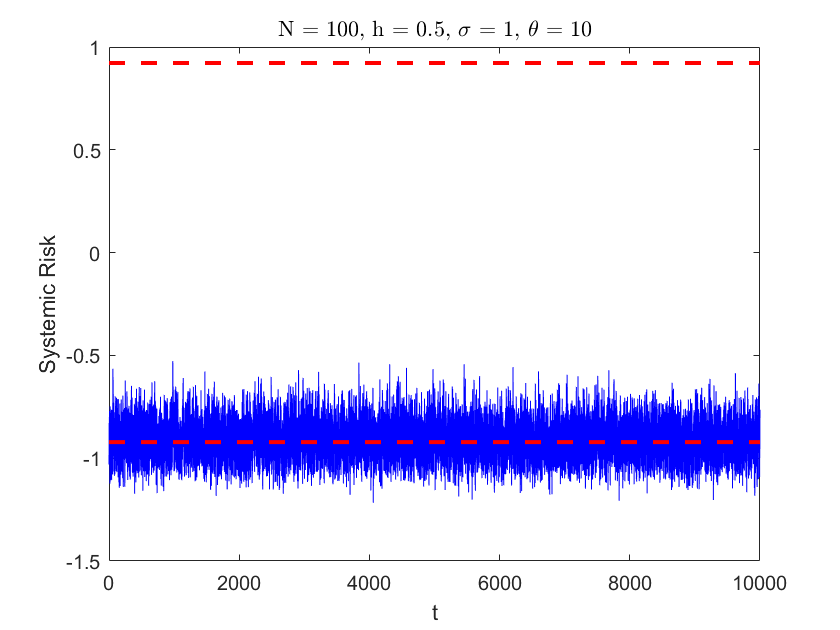

h = 0.5;
PlotSystemicRisk(t, N, h, sig, theta);

### Varying $N$

Increasing $N$ tends to have more stable behaviour.

Simulations for different $N = 40, 80, 120$.

Fix $h, \sigma, \theta$:

h = 0.1;
sig = 1;
theta = 10;

$N = 40$:

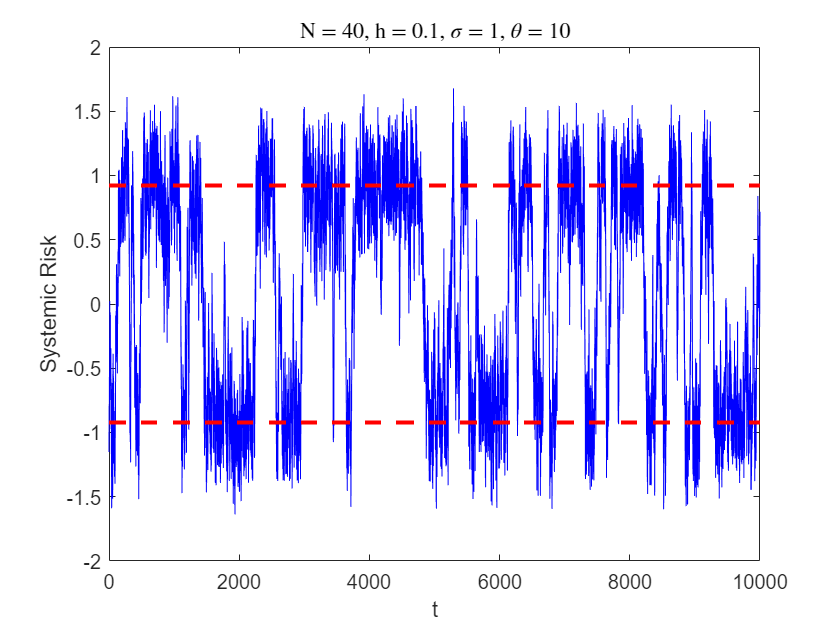

N = 40;
PlotSystemicRisk(t, N, h, sig, theta);

$N = 80$:

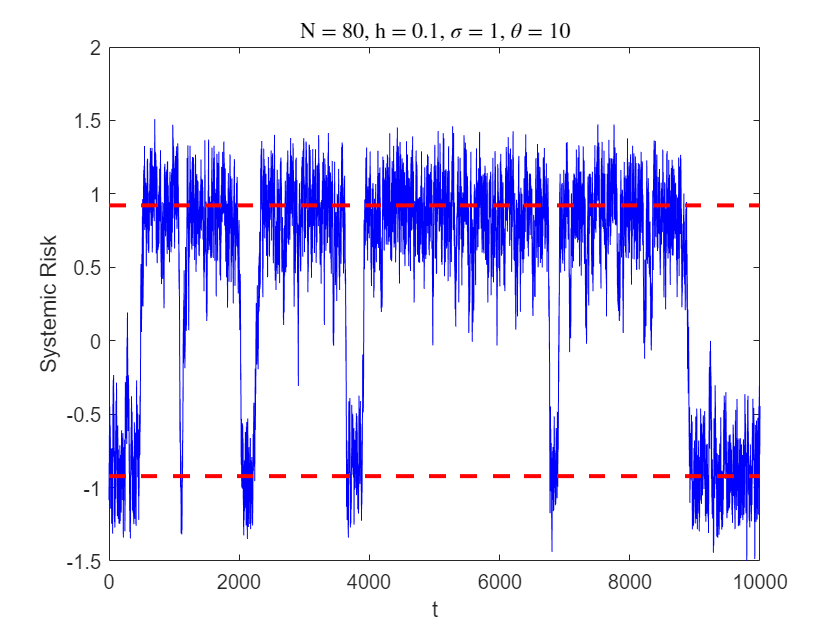

N = 80;
PlotSystemicRisk(t, N, h, sig, theta);

$N = 120$:

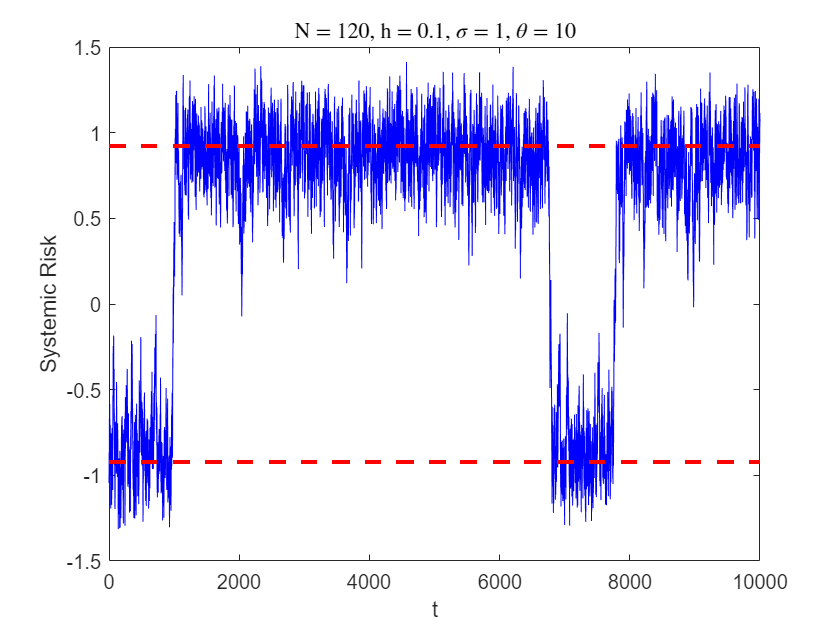

N = 120;
PlotSystemicRisk(t, N, h, sig, theta);

## Heterogeneous model

We consider a particular case in which each agent can have a different rate of mean reversion to the empirical mean:


$$$d x_{j}=-h \frac{\partial}{\partial x_{j}} V\left(x_{j}\right) d t+\sigma d w_{j}+\theta_{j}\left(\bar{x}-x_{j}\right) d t$$$


The discretisation is given by:


$$X_{j}^{n+1}=X_{j}^{n}-h U\left(X_{j}^{n}\right) \Delta t+\sigma \Delta W_{j}^{n+1}+\theta_{j}\left(\frac{1}{N} \sum_{k=1}^{N} X_{k}^{n}-X_{j}^{n}\right) \Delta t$$


The different values of $\theta_j$ are controlled by the parameters $\Theta_l$ and $\rho_l$.

### Effect of changes in $\sigma$

Here we take $K = 3$ and $\left\{\Theta_{l}\right\}_{l=1}^{K}=\left\{\Theta_{L}, \Theta_{M}, \Theta_{H}\right\}$for a system of low, medium, and high rates of mean reversion to the empirical mean, that is, the systemic risk. We also take $\left\{\rho_{l}\right\}_{l=1}^{K}=\left\{\rho_{L}, \rho_{M}, \rho_{H}\right\}$for the corresponding fractions.

Fix $N, h, \theta, \rho$:

N = 100;
h = 0.1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

For small h, we can calculate $\sigma_{c}^{\mathrm{div}}=\sqrt{\sum_{l=1}^{K} \frac{\rho_{l}}{\Theta_{l}} / \sum_{l=1}^{K} \frac{3 \rho_{l}}{2 \Theta_{l}^{2}}}+O(h) \approx 2.1217552$.

$\sigma = 1:$ Two stable equilibria

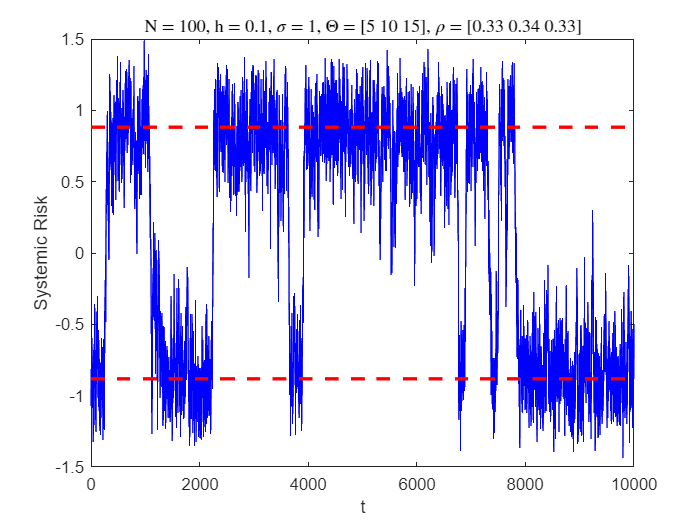

sig = 1;  
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\sigma = 2.1218$: One/Two stable equilibria. Note that this value of $\sigma$ approximately solves $\sum_{l=1}^{K} \frac{\rho_{l}}{\Theta_{l}}\left(1-3 \frac{\sigma^{2}}{2 \Theta_{l}}\right) / \sum_{l=1}^{K} \frac{\rho_{l}}{\Theta_{l}} = 0$, and $\sigma \approx \sigma_{c}^{div}$.

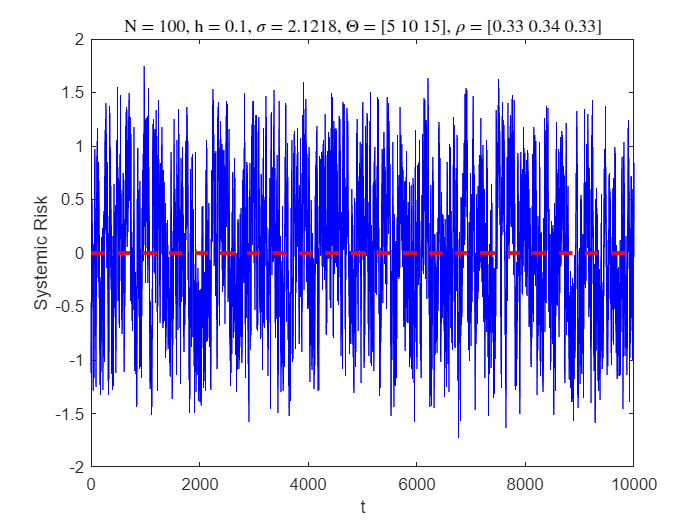

sig = 2.12175;
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\sigma = 3$: One stable equilibria

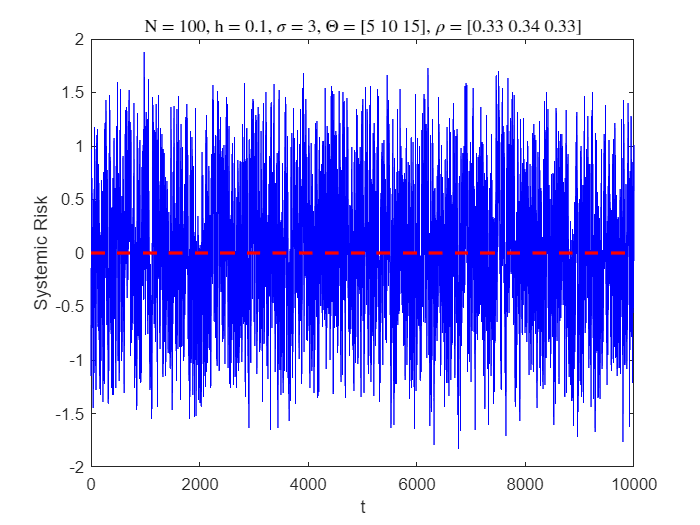

sig = 3;
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

### Varying $h$

Increasing h stabilizes the system. By stability we mean resistance to the transition of the empirical mean of the system from one state to the other.

Simulations for different $h = 0.02, 0.1, 0.5$

Fix $N, \sigma, \Theta, \rho$:

N = 100;
sig = 1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

$h = 0.02$:

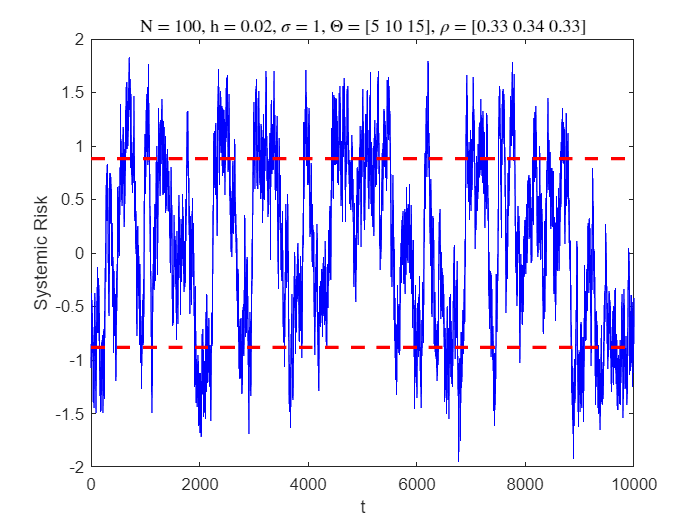

h = 0.02;
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$h = 0.1$:

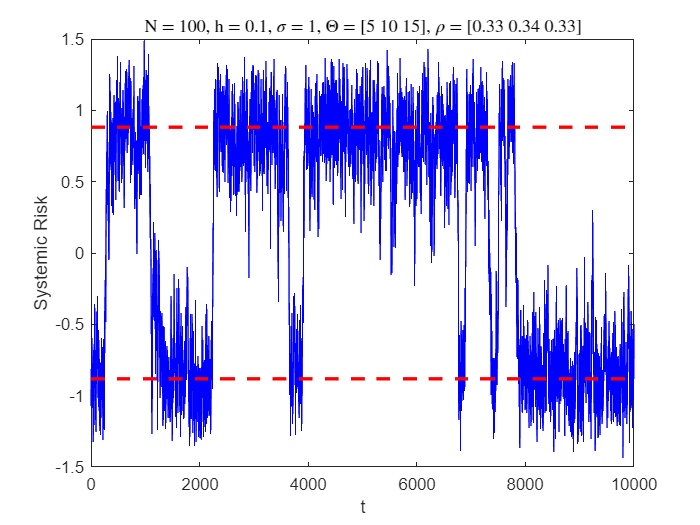

h = 0.1;
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$h = 0.5$:

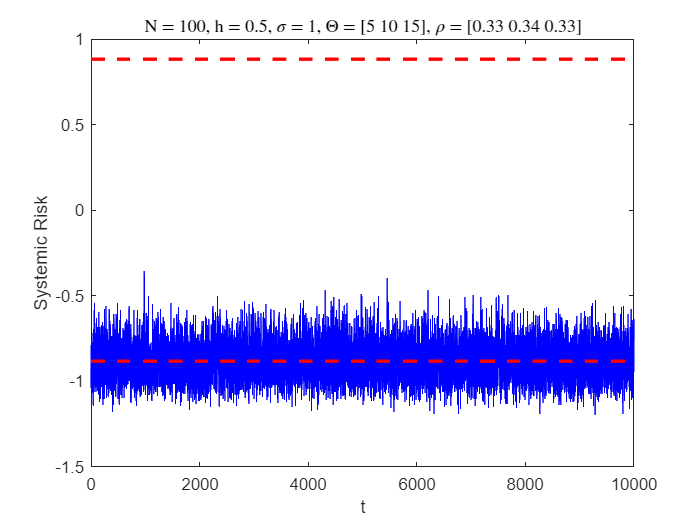

h = 0.5;
PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

### Varying $N$

Increasing $N$ tends to have more stable behaviour.

Simulations for different $N = 40, 80, 120$.

Fix $h, \sigma, \Theta, \rho$:

h = 0.1;
sig = 1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 1/3; rho_m = 1/3; rho_h = 1/3;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

$N = 80$:

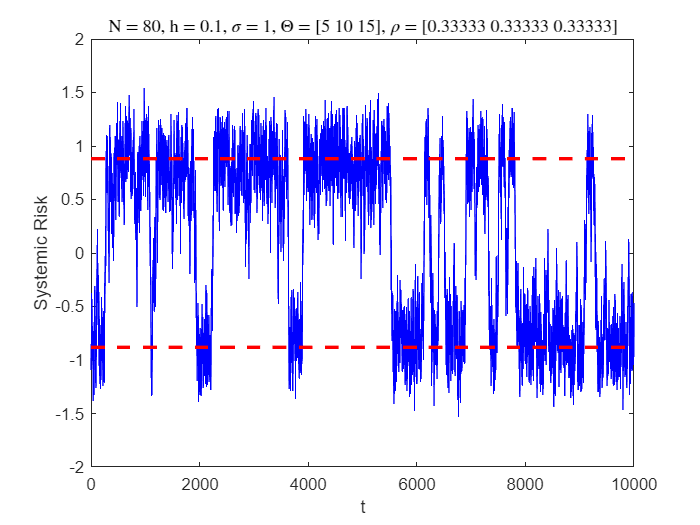

N = 80;

theta = [
    repelem(theta_l, 27, 1);
    repelem(theta_m, 27, 1);
    repelem(theta_h, 26, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$N = 120$:

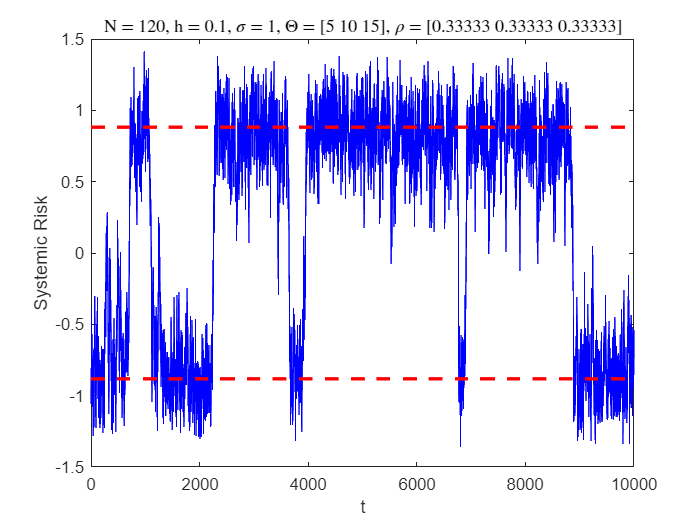

N = 120;

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$N = 160$:

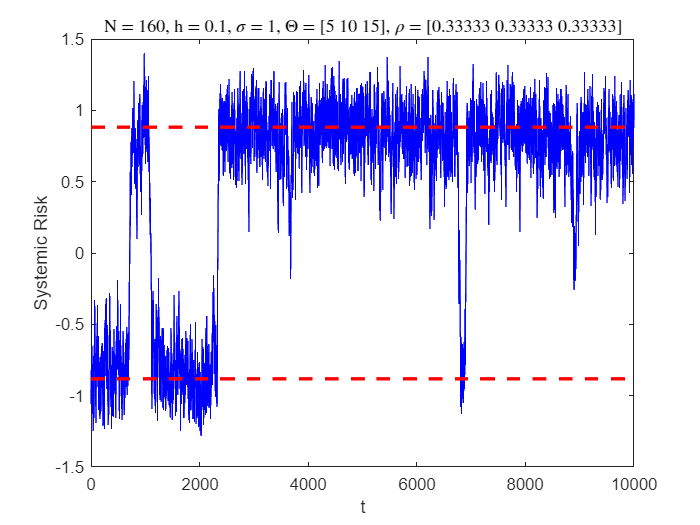

N = 160;

theta = [
    repelem(theta_l, 53, 1);
    repelem(theta_m, 54, 1);
    repelem(theta_h, 53, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

### Varying $\Theta$

Increasing diversity tends to destabilize the system.

Fix $N, h, \sigma, \rho$:

N = 100;
h = 0.1;
sig = 1;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;
rho = [rho_l; rho_m; rho_h];

$\Theta = [10; 10; 10]$: Two stable equilibria

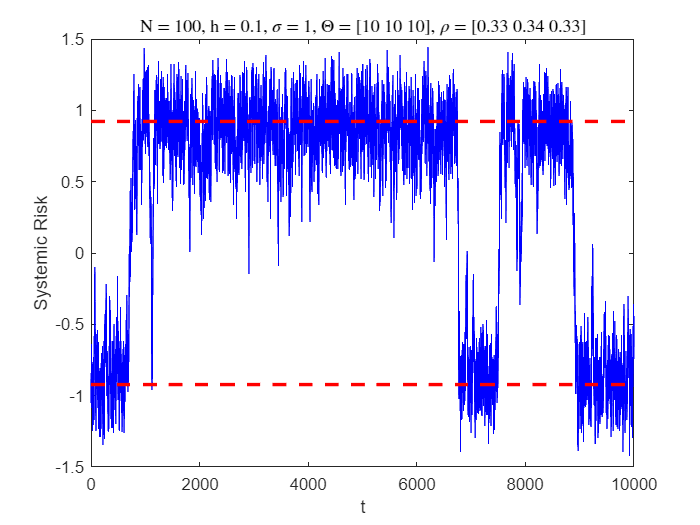

theta_l = 10; theta_m = 10; theta_h = 10;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\Theta = [6;10;14]$: Two stable equilibria

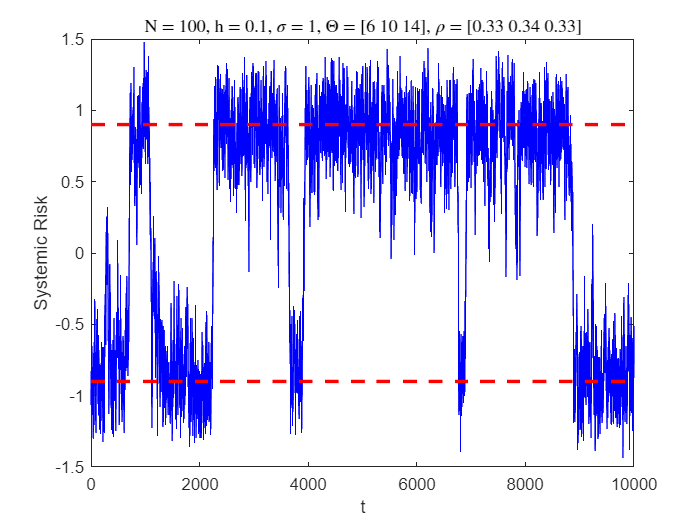

theta_l = 6; theta_m = 10; theta_h = 14;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\Theta = [2;10;18]$: Two stable equilibria

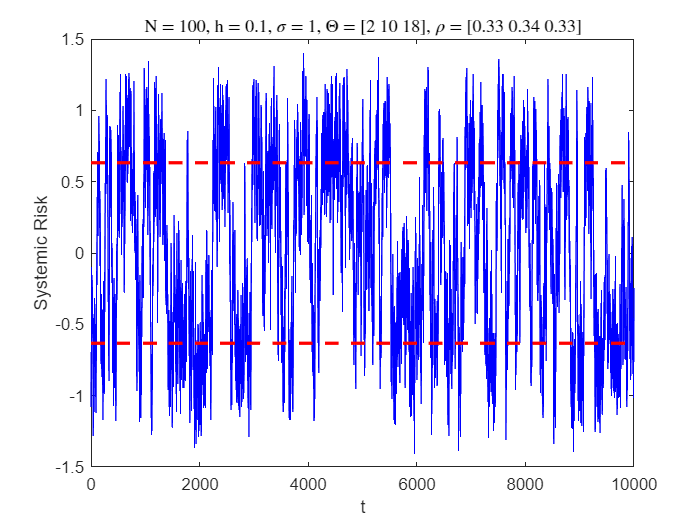

theta_l = 2; theta_m = 10; theta_h = 18;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

### Varying $\rho$

Increasing diversity tends to destabilize the system.

Fix $N, h, \sigma, \Theta$:

N = 100;
h = 0.1;
sig = 1;
theta_l = 5; theta_m = 10; theta_h = 15;
Theta = [theta_l; theta_m; theta_h];

$\rho = [0.1; 0.8; 0.1]$: Two stable equilibria

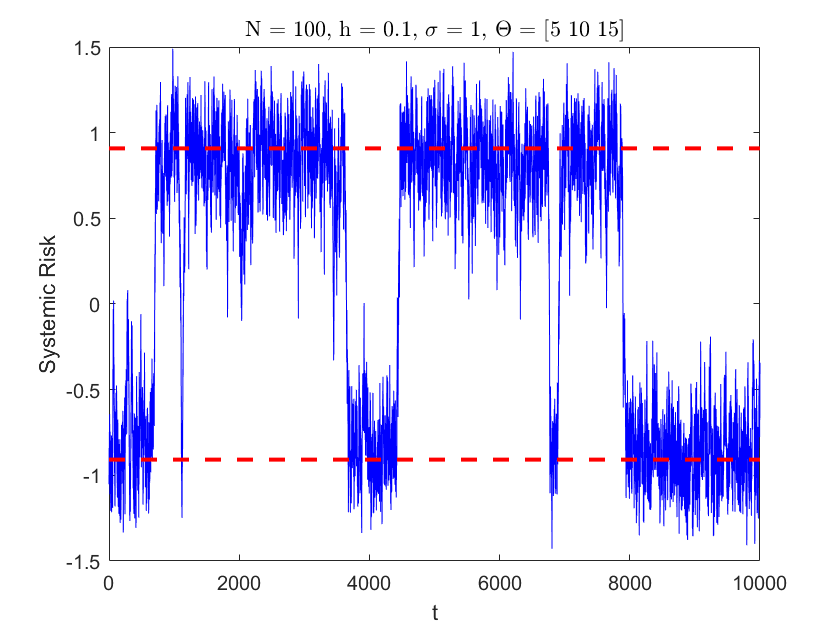

rho_l = 0.1; rho_m = 0.8; rho_h = 0.1;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\rho = [0.3; 0.4; 0.3]$: Two stable equilibria

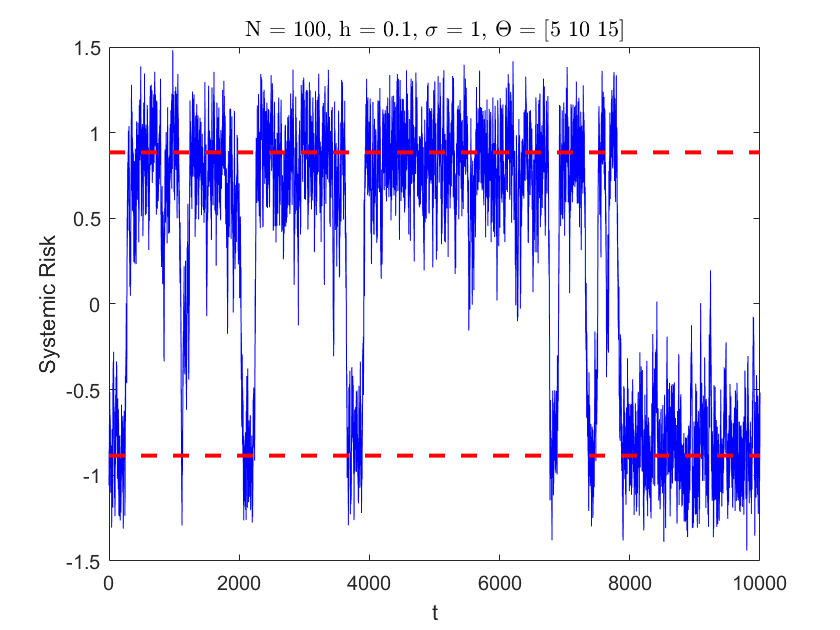

rho_l = 0.3; rho_m = 0.4; rho_h = 0.3;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

$\rho = [0.45; 0.1; 0.45]$: Two stable equilibria

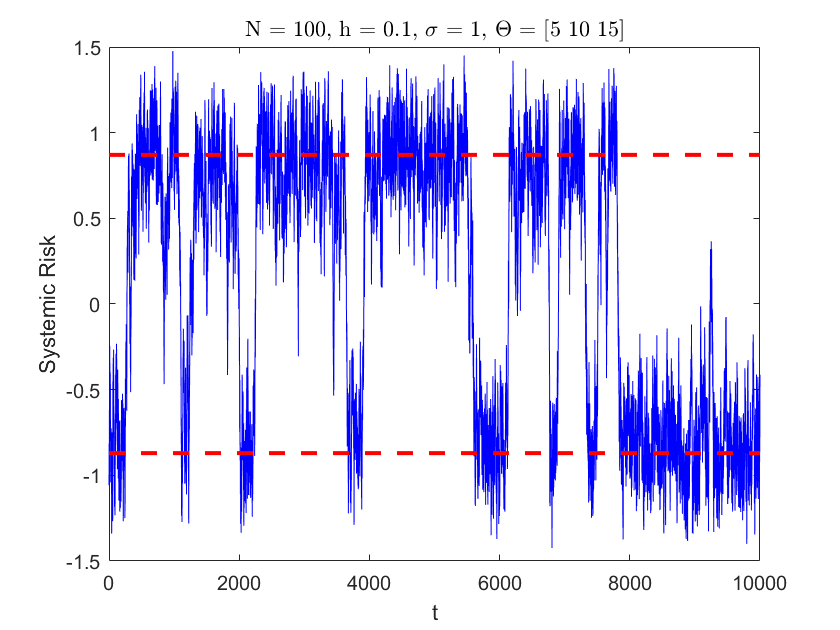

rho_l = 0.45; rho_m = 0.1; rho_h = 0.45;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho);

## Functions

Solve the SDE using standard Euler method.

Plot systemic risk as a function of parameters:

Plot homogeneous agents

function PlotSystemicRisk(t, N, h, sig, theta)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.*(mean(x) - x); 
    g = @(t, x) sig;    
   
    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts);
    xbar = mean(x, 2);
    
    % States of the system
    if (3 * sig^2 / (2 * theta)) < 1
        psi = sqrt(1 - 3*sig^2 / (2*theta)) * (1 + (6*h / sig^2) * (sig^2 / (2*sig))^2 * (1 - 2*(sig^2 / (2*sig))) / (1 - 3*(sig^2 / (2*sig))));
    else
        psi = 0;
    end
        
    % Plot
    figure; 
    plot(t, xbar, 'b');
    hold on
    % 1 line
    plot(t, psi .* ones(length(t), 1), 'r', ...
        'LineWidth', 2, ...
        'LineStyle', "--")
    hold on 
    % -1 line
    plot(t, -psi .* ones(length(t), 1), 'r', ...
        'LineWidth', 2, ...
        'LineStyle', "--")
    hold off
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\theta$ = ' num2str(theta)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');
end

Plot heterogeneous agents

function PlotSystemicRiskHeterogeneous(t, N, h, sig, theta, Theta, rho)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.*(mean(x) - x); 
    g = @(t, x) sig;        

    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts);
    xbar = mean(x, 2);
    
    % Nonzero solutions when h is small:
    if sig^2 < sum((rho ./ Theta)) / sum((3 .* rho ./ (2 .* Theta.^2)))
        psi = sqrt(sum((rho ./ Theta) .* (1 - 3*sig^2 ./ (2 .* Theta))) / sum((rho ./ Theta)));
    else
        psi = 0;
    end
    
    % Plot
    figure; 
    plot(t, xbar, 'b');
    hold on
    % 1 line
    plot(t, psi .* ones(length(t), 1), 'r', ...
        'LineWidth', 2, ...
        'LineStyle', "--")
    hold on 
    % -1 line
    plot(t, -psi .* ones(length(t), 1), 'r', ...
        'LineWidth', 2, ...
        'LineStyle', "--")
    hold off
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\Theta$ = [' num2str(Theta(:).') '], ' ...
        '$\rho$ = [' num2str(rho(:).') ']'], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');
    
end